clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;

% Identidades trigonométricas
nt = n.*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2.*nt);
s2nt = sin(2.*nt);
c3nt = cos(3.*nt);
s3nt = sin(3.*nt);

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2.*omega);
c2w = cos(2.*omega);
s3w = sin(3.*omega);
c3w = cos(3.*omega);

% Constantes de la memoria
sigma  = nt/2;
alpha1 =   omega +  theta_0;

beta1  =   sigma +   alpha1;
beta2  = 3*sigma + 2*alpha1;
beta3  =   sigma + 2*alpha1;
beta4  =   sigma - 2*alpha1;

kappa_i = 3*cos(2*INC) + 1;

u = alpha1 + 2*sigma;

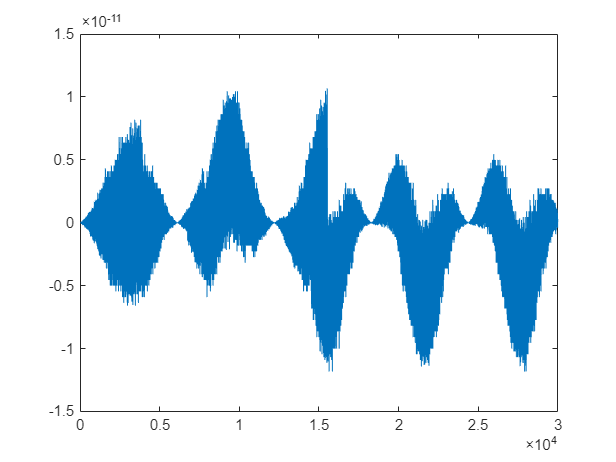

% Solución analítica
xJ2B = ((n + 6.*n.*sin((n.*t)./2).^2)./n).*x0 + (sin(n.*t)./n).*dx0 + ((4.*sin((n.*t)./2).^2)./n).*dy0 + ((R.^2.*(4.*sin((n.*t)./2).^2.*sin(INC).^2 - sin(n.*t).^2.*sin(INC).^2 - 6.*sin((n.*t)./2).^2 + 2.*sin(n.*t).^2.*sin(INC).^2.*sin(omega).^2 + 10.*sin((n.*t)./2).^2.*sin(INC).^2.*sin(omega).^2 + 2.*sin(n.*t).*sin(INC).^2.*cos(omega).*sin(omega) - 2.*cos(n.*t).*sin(n.*t).*sin(INC).^2.*cos(omega).*sin(omega)))./(a.*2)).*J2;
yJ2B = (-6.*n).*x0.*t + (6.*sin(n.*t)).*x0 + y0 + (-(4.*sin((n.*t)./2).^2)./n).*dx0 - 3.*dy0.*t + ((4.*sin(n.*t))./n).*dy0 + (-(R.^2.*(18.*n.*sin(INC).^2 - 24.*n + 36.*n.*sin(INC).^2.*sin(omega).^2))./(a.*8)).*t.*J2 + (-(R.^2.*(24.*sin(n.*t) - 16.*sin(n.*t).*sin(INC).^2 - sin(2.*n.*t).*sin(INC).^2 - 40.*sin(n.*t).*sin(INC).^2.*sin(omega).^2 + 2.*sin(2.*n.*t).*sin(INC).^2.*sin(omega).^2 + 2.*sin(2.*omega).*sin(n.*t).^2.*sin(INC).^2 + 16.*sin(2.*omega).*sin((n.*t)./2).^2.*sin(INC).^2))./(8.*a)).*J2;
zJ2 = (- ((3.*R.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0))./4 - (3.*R.^2.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0))./4)./a - (3.*R.^2.*n.*t.*(sin(- 2.*INC + omega + theta_0 + n.*t) - sin(2.*INC + omega + theta_0 + n.*t)))./(8.*a)).*J2;

x_t = (1 + 6.*sin(sigma).^2).*x0 + (sin(2*sigma)./n).*dx0 - (4./n).*sin(sigma).*dy0 ...
    - (R.^2.*J2)./(2.*a).*sin(sigma).^2 .* ( ...
        sin(INC).^2 .* (2.*cos(2.*beta1) + 7.*cos(2.*alpha1) - 9) ...
        + 6 ...
    );
y_t = 6.*sin(n.*t).*x0 + y0 ...
    - (4./n).*sin(sigma).^2.*dx0 ...
    + (4./n).*sin(n.*t).*dy0 ...
    - (6.*n.*x0 + 3.*dy0 - (3.*n.*R.^2.*J2)./(4.*a) .* ( ...
        4 + 3.*sin(INC).^2 .* (cos(2.*alpha1) - 2) ...
    )).*t ...
    + (R.^2.*J2)./(8.*a) .* ( ...
        sin(4.*sigma).*sin(INC).^2 ...
        - 4.*sin(2.*sigma) .* ( ...
            sin(alpha1).*sin(INC).^2 .* (sin(u) - 10.*sin(alpha1)) ...
            + 4.*cos(INC).^2 + 2 ...
        ) ...
        - 16.*sin(sigma).^2.*sin(2.*alpha1).*sin(INC).^2 ...
    );
z_t = cos(2*sigma).*z0 + (sin(2*sigma)./n).*dz0 ...
    + (3.*R.^2.*J2)./(4.*a).*sin(2.*INC) .* ( ...
        2*sigma.*cos(u) - cos(alpha1).*sin(2*sigma) ...
    );

figure; plot(t, xJ2B - x_t);

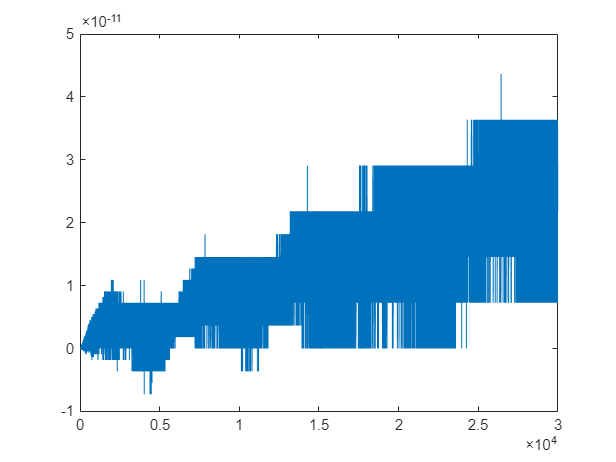

figure; plot(t, yJ2B - y_t);

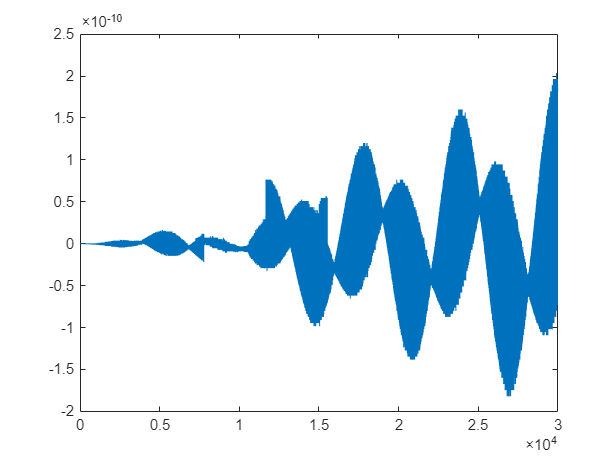

figure; plot(t, zJ2 - z_t);

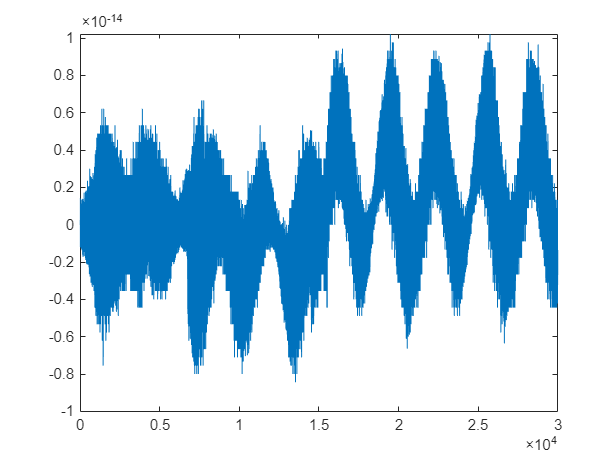




xdotJ2B = (6.*n.*cos((n.*t)./2).*sin((n.*t)./2)).*x0 + cos(n.*t).*dx0 + (4.*cos((n.*t)./2).*sin((n.*t)./2)).*dy0 + ((R.^2.*(4.*n.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).^2 - 2.*n.*cos(n.*t).*sin(n.*t).*sin(INC).^2 - 6.*n.*cos((n.*t)./2).*sin((n.*t)./2) + 2.*n.*cos(n.*t).*sin(INC).^2.*cos(omega).*sin(omega) + 4.*n.*cos(n.*t).*sin(n.*t).*sin(INC).^2.*sin(omega).^2 + 10.*n.*cos((n.*t)./2).*sin((n.*t)./2).*sin(INC).^2.*sin(omega).^2 - 2.*n.*cos(n.*t).^2.*sin(INC).^2.*cos(omega).*sin(omega) + 2.*n.*sin(n.*t).^2.*sin(INC).^2.*cos(omega).*sin(omega)))./(a.*2)).*J2;
ydotJ2B = dy0 + 2.*n.*x0 - 2.*n.*((dx0.*sin(n.*t))./n + (x0.*(n + 6.*n.*sin((n.*t)./2).^2))./n + (4.*dy0.*sin((n.*t)./2).^2)./n + (J2.*R.^2.*(4.*sin((n.*t)./2).^2.*sin(INC).^2 - sin(n.*t).^2.*sin(INC).^2 - 6.*sin((n.*t)./2).^2 + 2.*sin(n.*t).^2.*sin(INC).^2.*sin(omega).^2 + 10.*sin((n.*t)./2).^2.*sin(INC).^2.*sin(omega).^2 + 2.*sin(n.*t).*sin(INC).^2.*cos(omega).*sin(omega) - 2.*cos(n.*t).*sin(n.*t).*sin(INC).^2.*cos(omega).*sin(omega)))./(2.*a)) + (3.*J2.*R.^2.*n.*sin(INC).^2.*cos(2.*omega + 2.*n.*t))./(4.*a) - (3.*J2.*R.^2.*n.*cos(2.*omega).*sin(INC).^2)./(4.*a);
zdotJ2 = (-n.*sin(n.*t)).*z0 + cos(n.*t).*dz0 + (((3.*R.^2.*n.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0))./4 - (3.*R.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0))./4)./a - (3.*R.^2.*n.*(sin(- 2.*INC + omega + theta_0 + n.*t) - sin(2.*INC + omega + theta_0 + n.*t)))./(8.*a) - (3.*R.^2.*n.*t.*(n.*cos(- 2.*INC + omega + theta_0 + n.*t) - n.*cos(2.*INC + omega + theta_0 + n.*t)))./(8.*a)).*J2;

x_dot = 3.*n.*sin(2*sigma).*x0 ...
    + cos(2*sigma).*dx0 ...
    + 2.*sin(2*sigma).*dy0 ...
    + (n.*R.^2.*J2)./(4.*a) .* ( ...
        sin(2*sigma).*( ...
            sin(INC)^2.*( ...
                - 4*cos(2*beta1) ...
                - 5*cos(2*alpha1) ...
                + 9 ...
            ) ...
            - 6 ...
        ) ...
        - 4*sin(sigma).^2.*sin(2.*alpha1).*sin(INC).^2 ...
    );
y_dot = -12.*n.*sin(sigma).^2.*x0 ...
    - 2.*sin(2*sigma).*dx0 ...
    + (1 - 8.*sigma.^2).*dy0 ...
    + (n.*R.^2.*J2)./(4.*a).*sin(sigma) .* ( ...
        6*sin(sigma).*( ...
            + 3*sin(INC)^2.*cos(2.*alpha1) ...
            + kappa_i ...
        ) ...
        - sin(INC).^2.*( ...
            2*sin(beta2) ...
            + 5*sin(beta3) ...
            - 5*sin(beta4) ...
        ) ...
    );
z_dot = -n.*sin(2.*sigma).*z0 + cos(2.*sigma).*dz0 ...
    - (3.*n.*R.^2.*J2)./(4.*a).*sin(2.*INC) .* ( ...
        sin(2*sigma)*sin(alpha1) + 2.*sigma.*sin(u) ...
    );

figure; plot(t, xdotJ2B - x_dot);

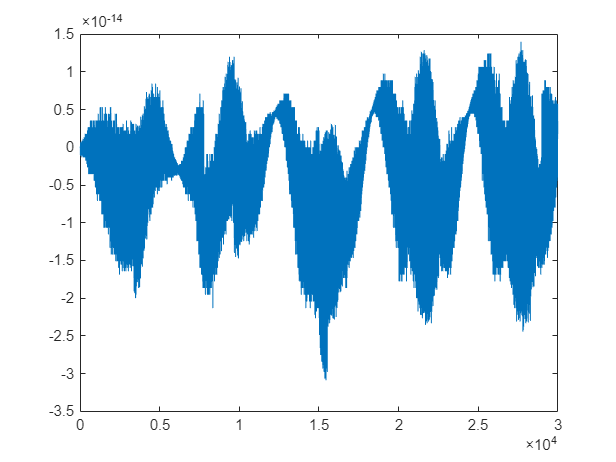

figure; plot(t, ydotJ2B - y_dot);

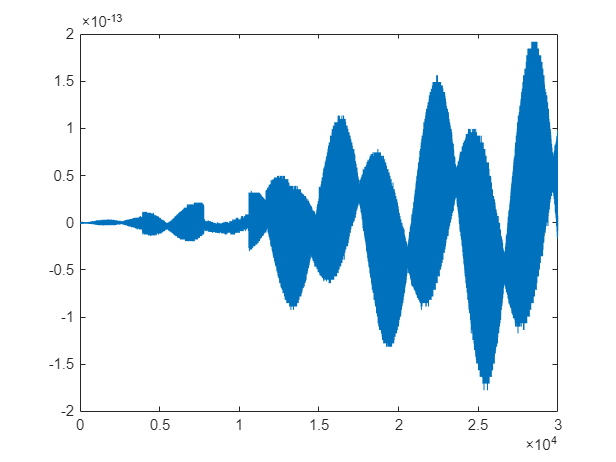

figure; plot(t, zdotJ2 - z_dot);